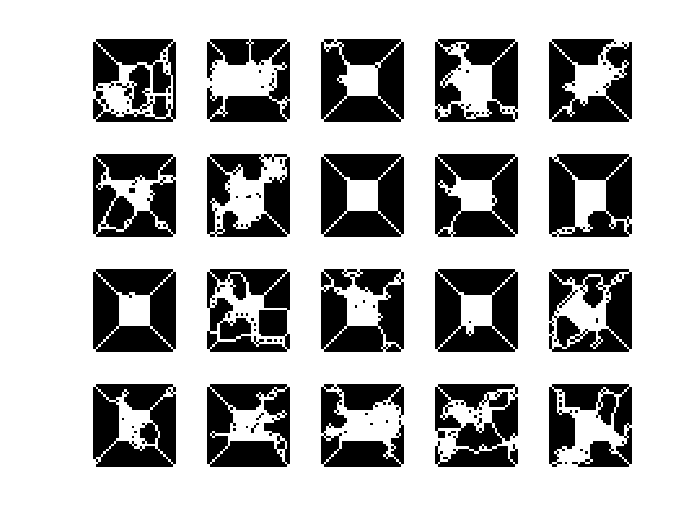

dataset_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Dataset\hpl\hpl_final\hpl_final_jpg\');
imds = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
images = imageSet(dataset_path);
perm = randperm(49676,20);
for i = 1:20
    subplot(4,5,i);
    imshow(bwmorph(imread(imds.Files{perm(i)}),'skel',10));
end

labelCount = countEachLabel(imds)

labelCount = 149×2 table
    Label    Count
    _____    _____

     1        347 
     10       329 
     100      332 
     101      299 
     102      323 
     103      327 
     104      338 
     105      330 
     106      343 
     107      343 
     108      340 
     109      341 
     11       324 
     110      340 
     111      343 
     112      329 


% img = readimage(imds,1);
% imageSize = size(img);
% numTrainFiles = 274;
% [imdsTrain,imdsTest,imdsVal] = splitEachLabel(imds,0.7, 0.15, 0.15,'randomized');
% augmenter = imageDataAugmenter( ...
%     'RandRotation',[0 360], ...
%     'RandScale',[0.5 1],    'RandXTranslation',[-3 3], ...
%     'RandYTranslation',[-3 3]);
% auimds = augmentedImageDatastore(imageSize,imdsTrain,'DataAugmentation',augmenter)
% layers = [
%     imageInputLayer([32 32 1],"Name","imageinput")
%     convolution2dLayer([5 5],8,"Name","conv_1","Padding","same","WeightLearnRateFactor",1)
%     batchNormalizationLayer
%     reluLayer("Name","tanh_1")
%     maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
%     crossChannelNormalizationLayer(5,"Name","crossnorm_1","Alpha",0.1)
%     convolution2dLayer([5 5],16,"Name","conv_2","Padding","same","Stride",[2 2],"WeightLearnRateFactor",1)
%     batchNormalizationLayer
%     reluLayer("Name","tanh_2")
%     maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
%     crossChannelNormalizationLayer(5,"Name","crossnorm_2","Alpha",0.1)
%     convolution2dLayer([5 5],32,"Name","conv_3","Padding","same","Stride",[2 2],"WeightLearnRateFactor",1)
%     batchNormalizationLayer
%     reluLayer("Name","tanh_3")
%     maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same","Stride",[2 2])
%     crossChannelNormalizationLayer(5,"Name","crossnorm_3","Alpha",0.1)
% %     convolution2dLayer([5 5],512,"Name","conv_4","Padding","same","Stride",[2 2],"WeightLearnRateFactor",1)
% %     batchNormalizationLayer
% %     reluLayer("Name","tanh_4")
% %     maxPooling2dLayer([2 2],"Name","maxpool_4","Padding","same","Stride",[2 2])
% %     crossChannelNormalizationLayer(5,"Name","crossnorm_4","Alpha",0.1)
% %     convolution2dLayer([5 5],1024,"Name","conv_5","Padding","same","Stride",[2 2],"WeightLearnRateFactor",1)
% %     batchNormalizationLayer
% %     reluLayer("Name","tanh_5")
% %     maxPooling2dLayer([2 2],"Name","maxpool_5","Padding","same","Stride",[2 2])
% %     crossChannelNormalizationLayer(5,"Name","crossnorm_5","Alpha",0.1)
%     fullyConnectedLayer(149,"Name","fc")
%     softmaxLayer("Name","softmax")
%     classificationLayer("Name","classoutput")];
% options = trainingOptions('adam', ...
%     'InitialLearnRate',0.01, ...
%     'MaxEpochs',4, ...
%     'Shuffle','every-epoch', ...
%     'ValidationData',imdsVal, ...
%     'ValidationFrequency',30, ...
%     'Verbose',false, ...
%     'Plots','training-progress');
% net = trainNetwork(auimds,layers,options);
% YPred = classify(net,imdsVal);
% YValidation = imdsVal.Labels;
% 
% accuracy = sum(YPred == YValidation)/numel(YValidation)